# MATLAB Tutorial 3. Step Response

## 1. 전달함수 생성

clc; clear
% 전달함수 식의 계수로 전달함수 객체 생성
T = tf([1 4], [1 3 2])


T =
 
      s + 4
  -------------
  s^2 + 3 s + 2
 
Continuous-time transfer function.



% 전달함수 수식 입력
s = tf('s');
G = (s+1)/(s^2+3*s+2)


G =
 
      s + 1
  -------------
  s^2 + 3 s + 2
 
Continuous-time transfer function.



% 피드백 시스템의 전달함수
% H: feedback gain
H = 4;
F = feedback(G, H)


F =
 
      s + 1
  -------------
  s^2 + 7 s + 6
 
Continuous-time transfer function.



## 2. 단위귀환 시스템의 응답 구하기

% 시스템 전달함수 정의
s=tf('s');                                     
G_s=4*(s+2)/(s*(s+3)*(s+7))


G_s =
 
        4 s + 8
  -------------------
  s^3 + 10 s^2 + 21 s
 
Continuous-time transfer function.



% 단위 귀환 시스템의 전달함수
sys=feedback(G_s,1)


sys =
 
          4 s + 8
  -----------------------
  s^3 + 10 s^2 + 25 s + 8
 
Continuous-time transfer function.



### 2.1 단위계단응답

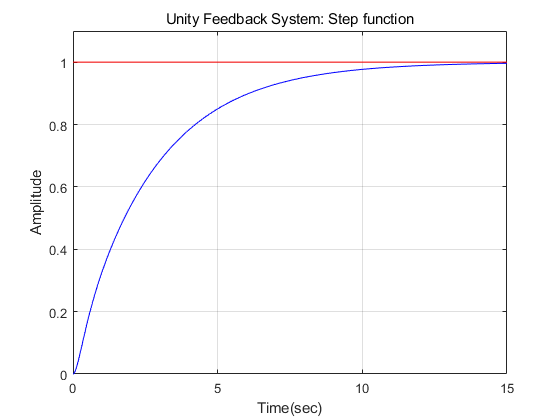

% 단위 계단 응답 계산 y=출력, t=시간
[y,t]=step(sys);
% 입력데이터 만들기: 출력시간의 길이만큼 1의 배열 생성
u=ones(size(t));

% 입력(u)과 출력(y) 그리기
plot(t,u,'r-', t,y,'b-')
axis([0 15 0 1.1])
xlabel('Time(sec)')
ylabel('Amplitude')
title('Unity Feedback System: Step function')
grid

### 2.2 단위경사응답

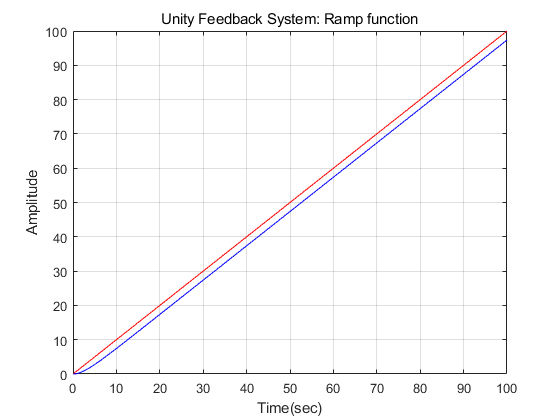

% 단위 램프 응답 계산 t=시간, u=입력, y=출력
t=0:0.1:100;
u=t;
[y,t]=lsim(sys,u,t);

% 입력(u)과 출력(y) 그리기
plot(t,u,'r-', t,y,'b-')
xlabel('Time(sec)')
ylabel('Amplitude')
title('Unity Feedback System: Ramp function')
grid

### 2.3 단위포물선응답

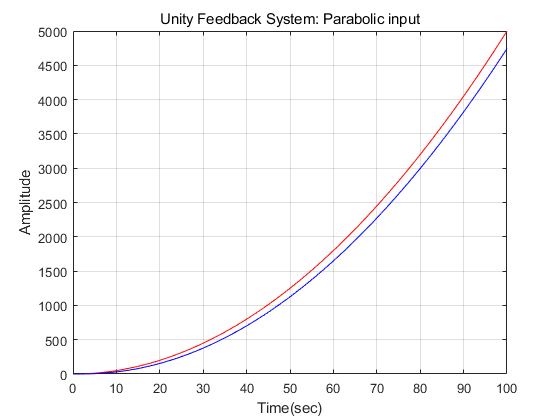

% 포물선 입력 응답 계산 t=시간, u=입력, y=출력
t=0:0.1:100;
u=0.5*t.*t;
[y,t]=lsim(sys,u,t);

% 입력(u)과 출력(y) 그리기
plot(t,u,'r-', t,y,'b-')
xlabel('Time(sec)')
ylabel('Amplitude')
title('Unity Feedback System: Parabolic input')
grid